# Primary Analysis of Three Displays

## Preparation

rift = RiftSim

rift =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 1
        spec_r: [2.6700e-26 2.6240e-26 2.5790e-26 3.0470e-06 9.1830e-07 1.0740e-06 2.7460e-06 2.9640e-06 8.6030e-07 1.7090e-06 2.2760e-26 2.2460e-26 6.9920e-06 2.1580e-06 4.6430e-06 2.0990e-26 2.0620e-26 2.0180e-26 1.9800e-26 1.9470e-26 1.9090e-26 … ]
        spec_g: [4.6880e-06 1.7540e-05 5.2740e-06 1.0430e-06 5.5930e-06 8.3730e-06 4.5230e-06 1.2970e-05 2.3860e-06 3.8470e-26 3.7940e-26 3.7430e-26 3.6770e-26 3.6120e-26 1.0150e-06 7.6440e-07 5.0900e-07 8.8490e-06 5.6630e-06 8.4590e-06 3.2670e-05 … ]
        spec_b: [7.1250e-06 4.6210e-08 4.2990e-26 9.8130e-06 2.9580e-06 3.4590e-06 8.8430e-06 3.9790e-26 1.1480e-07 7.7190e-06 1.2310e-05 1.1600e-05 2.4280e-05 2.9110e-05 1.2630e-05 1.19

hp = HPZ24xSim

Error using xlsread (line 257)
Unable to read XLS file C:\Users\wayne\Documents\GitHub\MIS_acquire\@HPZ24xSim\hpz24x_rgb.csv. File is not in recognized format.

Error in HPZ24xSim (line 14)
            spec_z24x = xlsread(datapath);

nec = NECPA271Sim

#### Spectral comparison of the red, green, and blue primary colors of the simulated displays

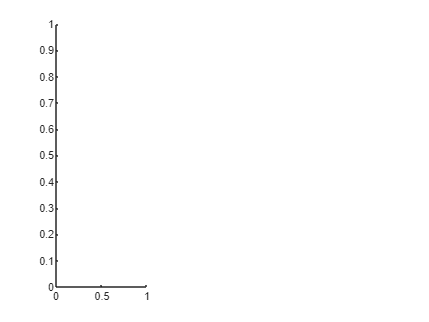

clf
subplot(1,3,1)

rift.show_spectra

Unable to resolve the name rift.show_spectra.

xlabel('Wavelengh')
ylabel('SPD')
title('Oculus Rift')

subplot(1,3,2)
hp.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('HP Z24X')

subplot(1,3,3)
nec.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('NEC PA271')

saveas(gcf,'compare3spectra.png')


#### Color gamuts of the three displays to be simulated

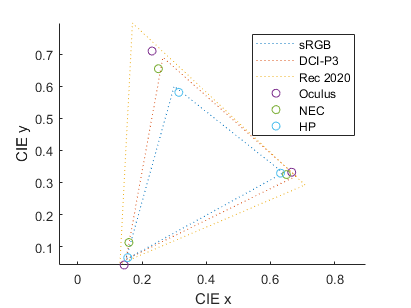

srgb = [0.64 0.33; 0.3 0.6 ; 0.15 0.06];
p3 = [0.68 0.32; 0.265 0.69 ; 0.15 0.06];
rec2020 = [0.708 0.292; 0.170 0.797 ; 0.131 0.046];

cc = ColorConversionClass;

clf
hold on
plot(srgb([1 2 3 1],1),srgb([1 2 3 1],2),':')
plot(p3([1 2 3 1],1),p3([1 2 3 1],2),':')
plot(rec2020([1 2 3 1],1),rec2020([1 2 3 1],2),':')

dp = rift;
XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')


dp = nec;
XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')

dp = hp;
XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')



axis equal
xlabel('CIE x')
ylabel('CIE y')


legend('sRGB','DCI-P3','Rec 2020','Oculus','NEC','HP')